

syms ang1 ang2 ang3 L1 L2 L3

xFormula = L1*cos(ang1) + L2*cos(ang1 + ang2) + L3*cos(ang1 + ang2 + ang3);
yFormula = L1*sin(ang1) + L2*sin(ang1 + ang2) + L3*sin(ang1 + ang2 + ang3);
x_dotFormula = diff(xFormula);
y_dotFormula = diff(yFormula);

h = [x_dotFormula; y_dotFormula; 0];
J = jacobian(h, [ang1 ang2 ang3]);
J_T = transpose(J);

Analysis of the relationship between 2 optimisation metrics and the robots joints range of motions:

max) det(JJ^T)

Algebra

syms ang1 ang2 ang3 L1 L2 L3 phi real 

L1 = 1;
L2 = 1;
L3 = 1;

phi = ang1 + ang2 + ang3;


Posx = L1*cos(ang1) + L2*cos(ang1 + ang2) + L3*cos(ang1 + ang2 + ang3);
Posy = L1*sin(ang1) + L2*sin(ang1 + ang2) + L3*sin(ang1 + ang2 + ang3);

Pwx = L1*cos(ang1) + L2*cos(ang1 + ang2);
Pwy = L1*sin(ang1) + L2*sin(ang1 + ang2);

c2 = (Pwx^2 + Pwy^2 - L1^2 - L2^2)/(2*L1*L2);

s2 = sqrt(1-c2^2);

ang2 = atan2(s2,c2);

c1 = ((L1 + L2*c2)*Pwy - L2*s2*Pwx)/(Pwx^2 + Pwy^2);
s1 = ((L1 + L2*c2)*Pwx + L2*s2*Pwy)/(Pwx^2 + Pwy^2);

ang1 = atan2(s1,c1);


ang3 = phi - ang1 - ang2;


J = [-L1*sin(ang1)-L2*sin(ang1+ang2)-L3*sin(ang1+ang2+ang3), -L2*sin(ang1+ang2)-L3*sin(ang1+ang2+ang3), -L3*sin(ang1+ang2+ang3);
    L1*cos(ang1)+L2*cos(ang1+ang2)+L3*cos(ang1+ang2+ang3), L2*cos(ang1+ang2)+L3*cos(ang1+ang2+ang3), L3*cos(ang1+ang2+ang3)];
J_T = transpose(J);


detminJ = det(J *J_T);

Error using sym/subsindex (line 855)
Invalid indexing or function definition. Indexing must follow MATLAB indexing. Function arguments must be symbolic variables, and function body must be sym expression.

Numerical


L1 = 0.2817;
L2 = 0.2689;
L3 = 0.0862;

px = 0;
py = 0;
phi = 0;



%phi = ang1 + ang2 + ang3;


%Posx = L1*cos(ang1) + L2*cos(ang1 + ang2) + L3*cos(ang1 + ang2 + ang3);
%Posy = L1*sin(ang1) + L2*sin(ang1 + ang2) + L3*sin(ang1 + ang2 + ang3);

%Pwx = L1*cos(ang1) + L2*cos(ang1 + ang2);
%Pwy = L1*sin(ang1) + L2*sin(ang1 + ang2);

Pwx = px - L3*cos(phi);
Pwy = py - L3*sin(phi);

c2 = (Pwx^2 + Pwy^2 - L1^2 - L2^2)/(2*L1*L2);
if c2 > 1
    
   s2 = NaN;
   %not a number
else
    
s2 = sqrt(1-c2^2);

ang2 = atan2(s2,c2);

c1 = ((L1 + L2*c2)*Pwy - L2*s2*Pwx)/(Pwx^2 + Pwy^2);
s1 = ((L1 + L2*c2)*Pwx + L2*s2*Pwy)/(Pwx^2 + Pwy^2);

ang1 = atan2(s1,c1);


ang3 = phi - ang1 - ang2;


J = [-L1*sin(ang1)-L2*sin(ang1+ang2)-L3*sin(ang1+ang2+ang3), -L2*sin(ang1+ang2)-L3*sin(ang1+ang2+ang3), -L3*sin(ang1+ang2+ang3);
    L1*cos(ang1)+L2*cos(ang1+ang2)+L3*cos(ang1+ang2+ang3), L2*cos(ang1+ang2)+L3*cos(ang1+ang2+ang3), L3*cos(ang1+ang2+ang3)];
J_T = transpose(J);


detminJ = det(J *J_T);


    
end



Changed to be function


px = 0.62;
py = 0;

phi = linspace(1, 360, 360*100)*2*pi/360; 
detJJ = phi;

xTest = 100;
linspaceX = linspace(0, 0.62, xTest);
maxdetJJ = zeros(2, xTest);
for index = 1:length(linspaceX)
    px = linspaceX(index);

for angle = 1:length(phi)
   
    detJJ(angle) = calcDetJJ(phi(angle), px, py);
    
    
end

[maxVal, indexMax] = max(detJJ);
maxdetJJ(:,index) = [phi(indexMax)*360/(2*pi), maxVal];
end
maxdetJJ

maxdetJJ =    33.7497  214.3516  214.8403  215.2392  215.5384  215.7578  215.9173  216.0071  216.0370  216.0270  215.9772  215.8974  215.7877  215.6680  215.5184  215.3589  215.1993  215.0398  214.8702  214.7107  214.5611  214.4215  214.3018  214.1921  214.1023  214.0425  214.0026  213.9926  214.0226  214.0724  214.1721  214.3018  214.4713  214.6907  214.9400  215.2392  215.5882  215.9772  216.4060  216.8747  217.3833  217.9318  218.5102  219.1185  219.7468  220.3950  221.0532  221.7313  222.4194  223.1075
    0.0028    0.0029    0.0030    0.0032    0.0033    0.0034    0.0036    0.0038    0.0039    0.0041    0.0042    0.0044    0.0046    0.0048    0.0049    0.0051    0.0053    0.0055    0.0057    0.0059    0.0061    0.0062    0.0064    0.0066    0.0068    0.0070    0.0072    0.0074    0.0076    0.0078    0.0079    0.0081    0.0083    0.0085    0.0086    0.0088    0.0090    0.0091    0.0093    0.0094    0.0096    0.0097    0.0098    0.0099    0.0101    0.0102    0.0103    0.0104    0.01

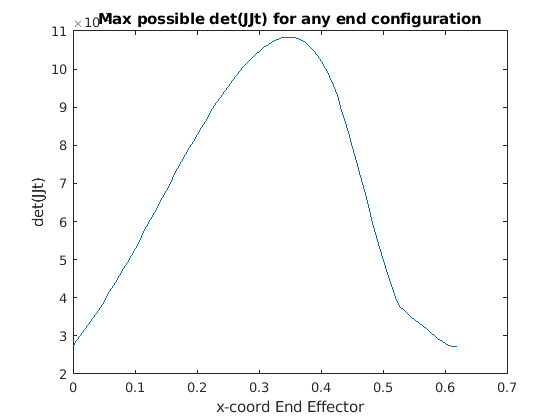

figure
plot(linspaceX, maxdetJJ(2,:))
xlabel('x-coord End Effector')
ylabel('det(JJt)')
title('Max possible det(JJt) for any end configuration')

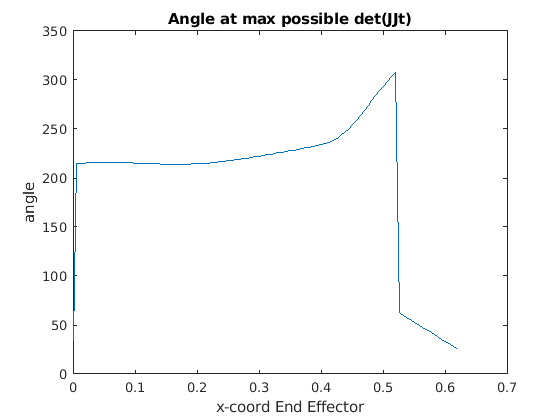


figure
plot(linspaceX, maxdetJJ(1,:))
xlabel('x-coord End Effector')
ylabel('angle')
title('Angle at max possible det(JJt)')